# Project assignment LEDS - Alessandro Binci (0001189831)

(Assignment done with MATLAB R2024b version)

clear all
close all
addpath(fullfile(pwd,'Functions'));
addpath(fullfile(pwd,'Functions','Estimation Functions'));
addpath(fullfile(pwd,'Functions','Classification Functions'));

# Exercise 1: Estimation 

**1) - Understanding the model structure & plotting the auocorrelations:**

N=5000; %set it at a right amount 
Student = 'Alessandro Binci';
Matriculation = '0001189831';
[Measurements] = IdentifyThis(N,Student,Matriculation);
u=Measurements.u;
y=Measurements.y;

From the measurements we can see that we have to deal with an AR model. Now we must divide the dataset in Training (70%) and Validation (30%) sets, in the following way.

sample_division = floor(0.7*N);
y_train = y(1:sample_division);
y_valid = y(sample_division+1:end);
u_train = u(1:sample_division);
u_valid = u(sample_division+1:end);

And then we can **plot the data **as follows. We can plot ***y *** and ***u ***in the same graph (since u is a vector of all zeroes and it is not annoing for the visualization). We'll divide the plotting samples from the first one to the 1000th, to obtain plot more clear.

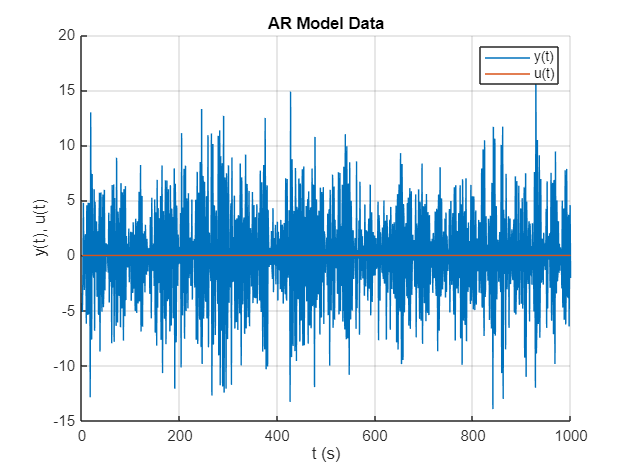

t = 1:N;
figure();
hold on;
grid on;
plot(t(1:1000), y(1:1000));
plot(t(1:1000), u(1:1000));
xlabel('t (s)');
ylabel('y(t), u(t)');
title('AR Model Data');
legend('y(t)', 'u(t)');

drawnow;

An **AR Model** is defined in the following way:

$A(z^{-1})y(t) = e(t)$ or also $y(t) = {\frac{1}{A(z^{-1})}e(t)$ where the error $e(t)
$ is a *white process *such as $e(t) = w(t)
$ with zero mean and variance $\sigma{^2}_w$.

The general form of an **AR **will be: $y(t) = {\frac{1}{A(z^{-1})}w(t)$. 

While the extended form can be written as: $y(t) + a_1y(t-1) + ... + a_ny(t-n) = e(t)$. Moreover, the system order **p **is equal to n, so we have to find n paramenters: $a_1 \cdots a_n$ and the complexity of the model is **p = n**.

Our model is therefore characterized by a process without the exogenous part (the input part $u(t)$) and wich only depends on the error, which is a white signal.

Now we are going to plot the **output** autocorrelation function up to delay 15 (as requested by the exercise). So:

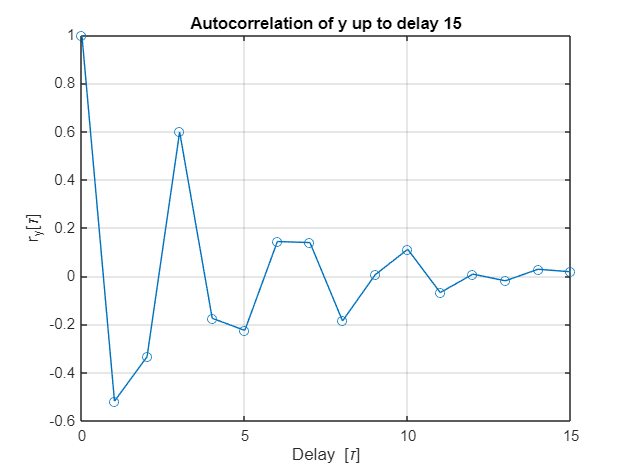

[autoCorFunct,lags]= autocorr(y,'NumLags',15); %autocorr is a function implemented by the Econometrics toolbox

% we can notice that the autocorrelation function is already normalized.

figure();
ax = plot(lags,autoCorFunct,'o-'); % command 'o-' used to notice that we have discrete points
grid on;
xlabel("Delay [\tau]");
ylabel("r_y[\tau]");
title("Autocorrelation of y up to delay 15");
xlim([0 15]); %for the interval between 0 and 15

drawnow;

The output autocorrelation for lags 0–15 shows oscillations: small negative values at the first lags, a positive peak near lag 3, then alternating signs with increasing lags. This pattern is consistent with the behaviour of a stable AR model, since the autocorrelation approaches zero by about lag 15.

The precise model order will be selected via information criteria in the next step.

**2 & 3) - Definition of the required estimation algorithm and estimation of the model order:**

We can start from the linear regression form:    $y\left(t\right)=\varphi^T \theta +e\left(t\right)$ 

where $\varphi(t) = [-y(t-1) -y(t-2) - ... -y(t-n)]^T$ and $\theta = [a_1 \space a_2 \space ... \space a_n]^T$.

The linear regression form can be also written in matrix form, which is: $Y=-H_y \left(n\right)\theta +\varepsilon$ ,  where $\varepsilon$ is the prediction error (or residuals). We need to find the batch estimator $\hat{\theta}$.

We choose this estimator, which is equal to: $\widehat{\theta} ={\left(H^T H\right)}^{-1} H^T Y$, because it minimizes the loss function $J\left(\theta \right)={\left\|Y-H\theta \right\|}^2 =\varepsilon^T \varepsilon$.

Since the batch algorithm is not efficent for a large number of samples, due to the high computational cost of the Hankel matrix $H_y(n)$, we use the *Recursive Least Square Algorithm*, in particular, as asked by the exercise, we'll exploit the version which uses the *Matrix Inversion Lemma*, so we can update recursively the estimation without inverting matrices at each step. It's better, in this case, to use the ***RLS III.*** 

We can proceed in the following way:

**RLS III:**

- starting from $S(t) = \sum_{k=1}^{t}\varphi(k)\varphi(k)^T$

- We exploit the *Matrix Inversion Lemma*, avoiding matrix inversion at each step

Then, we must obtain the following algorithm:

- 
$$S(t)^{-1} = S(t-1)^{-1} \;-\;\frac{S(t-1)^{-1}\,\varphi(t)\,\varphi^\top(t)\,S(t-1)^{-1}}
{\, 1 + \varphi^\top(t)\,S(t-1)^{-1}\,\varphi(t)\,}$$


- 
$$K(t) = \frac{1}{t}\, S(t)^{-1}\,\varphi(t)$$


- 
$$\varepsilon(t) = y(t) - \varphi^\top(t)\,\hat{\theta}(t-1)$$


- 
$$\hat{\theta}(t) = \hat{\theta}(t-1) + K(t)\,\varepsilon(t)$$
 

We'll use the following **functions** to implement the recursive algorithm:

- `rls3_AR: `function which develop all the steps of the algorithm and gives the final estimated parameters. An initialization of the batch estimator is used.

- `leastSquare: `Inside the `rls3_AR. `Function which computes the estimated parameters within the *LS estimator*.

- `initS_0: `Inside the `rls3_AR. `Function which computes the inizitialization $S(0)$.

- `phi_k: `Inside the `rls3_AR` and `initS_0. `Function which gives the vector $\varphi(k)$ of the past outputs

After that, we can estimate also the model order **p **and compute the loss function $J(\theta)$. In this way, we can also show the difference between considering the minimum cost function only, and the utilization of an approach based on *Criteria With Complexity Terms. *We choose to use the  *MDL (Minimum Description Length Criterion)*, which is the one that leads, in general, to models of lower complexity.

To do this final steps we'll use the following **functions**:

- `lossFunctJ: `function which computes the loss functions $J(\theta)$.

- `MDLapproach: `function which develop the Minimum Description Length algorithm.

limit = min(20, floor(N/6));                  %we impose a limit on the maximum model order it can arrive
J = zeros(limit,1);                           %and we use this limit for J...
MDL=zeros(limit,1);                           %...and MDL

for p=1:limit
    N_batch = 5*p;                                  %N_batch chosen accordingly to the model complexity increasing
    Theta_RLS = rls3_AR(y_train,p,N_batch);         %estimation of parameters through RLS III (on the training set)
    J(p) = lossFunctJ(y_valid,Theta_RLS);           %computation of the loss function (on the validation set to have it more accurate)

    MDL(p)=MDLapproach(y_valid,J(p),p);             %MDL approach 
end

We now extract the min value of the J and the respectively model. Same thing is done with the MDL method, the different obtained results are shown by displaying and plotting them. 

[value,n_minJ]=min(J);                                     % Finding n for lowest J
disp('min J and corresponding p');

min J and corresponding p


disp([value, n_minJ]);                                     % Displaying the corresponding value of cost function J

    1.0025   16.0000



[valueMDL,n_minMDL]=min(MDL);                              % Finding n for lowest J by MDL criterion
disp('minMDL and corresponding p');

minMDL and corresponding p


disp([valueMDL, n_minMDL]);                                % Displaying the corresponding value with MDL criterion

   58.9886    6.0000



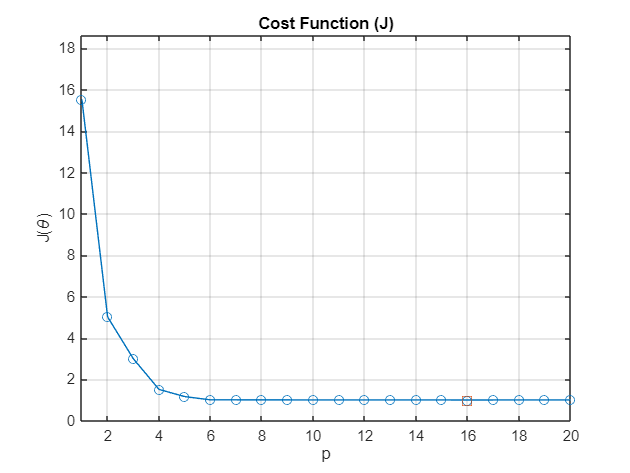

figure;

% Plotting the behaviour of J
plot(1:limit,J,'-o');
hold on
plot(n_minJ,J(n_minJ),'s', 'MarkerSize',8, 'DisplayName','min J');
grid on;
xlabel('p');
ylabel('J(\theta)');
title('Cost Function (J)');
xlim([1 limit]);
ylim([0 max(J)*1.2]);
hold off

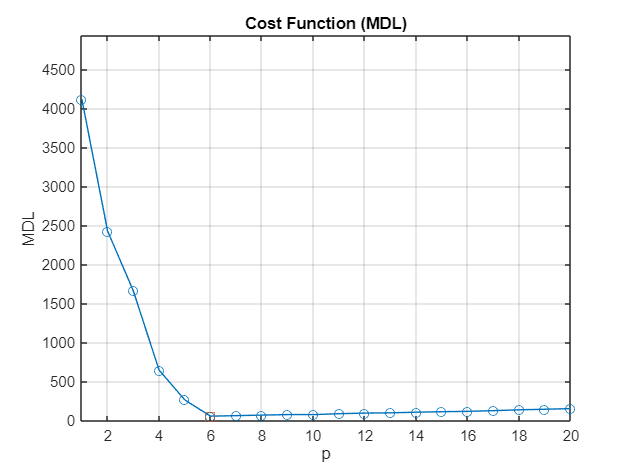

drawnow;

figure;
% Plotting the behaviour of J undel MDL assumptions                                  
plot(1:limit, MDL,'-o');
hold on
plot(n_minMDL,MDL(n_minMDL),'s', 'MarkerSize',8, 'DisplayName','min MDL');
grid on;
xlabel('p');
ylabel('MDL');
title('Cost Function (MDL)');
xlim([1 limit]);
ylim([0 max(MDL)*1.2]);     
hold off;

drawnow;

So we can consider ***p****=6* as the true estimated order of the model (as we can also see from the MDL plot), which practically is:

**AR model** :  $y(t) = -a_1y(t-1)-a_2y(t-2)-a_3y(t-3)-a_4y(t-4)-a_5y(t-5)-a_6y(t-6) + w(t)$ 

We can also check if our RLS III algorithm matches the Least Square with the true estimated order [*p=6*], in order to verify the correctness of the code implementation.

n_min = n_minMDL;

N0=5*n_min;
ThetaLS = leastSquare(y_train,n_min);
ThetaRLS = rls3_AR(y_train,n_min,N0);

compare = [ThetaLS ThetaRLS];
disp(compare);

    2.4886    2.4906
    3.9938    3.9981
    4.1262    4.1319
    3.0604    3.0652
    1.4569    1.4594
    0.4256    0.4260



As we can see, our *Recursive Least Square algorithm* matches the batch LS solutions if we use the estimated true order. We can now plot the parameter to see the behaviour of the model:

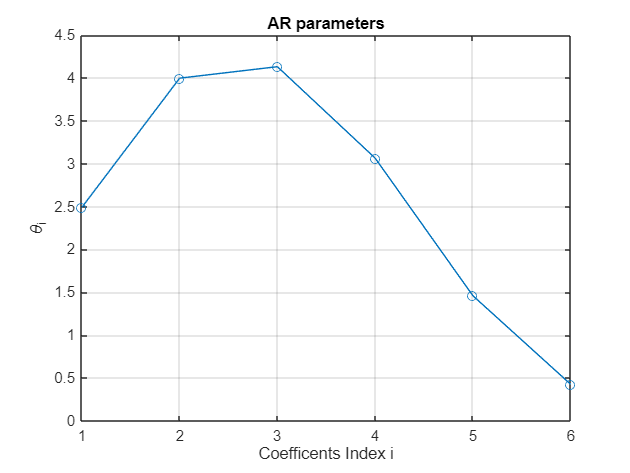

figure();
plot(ThetaRLS, '-o');
xlabel('Coefficents Index i');
ylabel('\theta_i');
title('AR parameters');
grid on;

drawnow;

**4) - Validation of the model:**

We can now proceed to the *Model Assessment (Validation)* which practically consists in evaluating the capability of the identified model to describe the process that has generated the data in a way compatible with its planned use. To do so, we could perform two tests: the **Whiteness Test **and the **Cross Correlation Test**. We just need one of them to validate the model, we choose in favor of the first one, which can be implemented in the following way:

- **Whiteness test of and AR model**

Performing this test means that the assumption "*e(t) is a zero-mean white noise process*" holds. This means that the residual $\varepsilon \left(t,{\hat{\theta} }_N \right)$ sequence is a sequence of zero mean white noises.

The binary test that must be performed will be:


$$\left\lbrace \begin{array}{ll}
H_0 :\varepsilon \left(t\right)\;\textrm{ia}\;\textrm{zero}\;\textrm{mean}\;\textrm{white}\;\textrm{process}\longrightarrow  & \textrm{accept}\;\textrm{the}\;\textrm{model}\\
H_1 :\textrm{not}\;H_{0\;} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\longrightarrow  & \textrm{reject}\;\textrm{the}\;\textrm{model}
\end{array}\right.$$


If a process is white, it means that its autocorrelation function should be :


$$\hat{r_{\varepsilon } } \;\left(\tau \right)=\left\lbrace \begin{array}{ll}
{\sigma^2 }_{\varepsilon }  & \textrm{for}\;\tau =0\\
0 & \textrm{for}\;\tau \not= 0
\end{array}\right.$$


 If we consider the first m sample autocorrelations of $\varepsilon \left(t\right)$ and define the vector    


$$\hat{r_{\varepsilon } } \;\left(\tau \right)={\left\lbrack \hat{r_{\varepsilon } } \;\left(1\right),\ldotp \ldotp ,\hat{r_{\varepsilon } } \;\left(m\right)\right\rbrack }^T$$
         

Now, if $H_0$  is true, asymptotically holds that:


$$\left\lbrace \begin{array}{ll}
\hat{r_{\varepsilon } } \;\left(0\right)\;\longrightarrow  & {\sigma^2 }_{\varepsilon } \\
\hat{r_{\varepsilon } } \;\left(\tau \;\right)\longrightarrow  & 0
\end{array}\right.$$
     
$$\forall \tau \not= 0$$


Morover, it's possible to prove that the random vector  $\hat{r_{\varepsilon } } \;\left(\tau \;\right)$ asymptotically tends to be Gaussian distributed with mean zero and a covariance matrix *P*: 


$$\left\lbrace \begin{array}{ll}
\sqrt{N}\;\hat{r_{\varepsilon } } \;\;\;\;\;\;\;\longrightarrow \;\;\;\;N\left(0,P\right)\; & \\
P=\;\lim_{N\to \infty } \;E\left\lbrack N\;\hat{r_{\varepsilon } } \hat{{\;\;r}_{\varepsilon } } {\;}^T \right\rbrack =\sigma_{\varepsilon }^4 I & 
\end{array}\right.$$


If this holds, practically means that we can perform a *Gaussian distribution* test.

In practice we will perform *m* binary tests of Gaussian distribution on the normalized autocorrelation factor $\hat{\gamma}$, that is defined as


$$\hat{\gamma} \left(\tau \right)=\frac{\hat{r_{\varepsilon } } \;\left(\tau \;\right)\;\;}{\hat{r_{\varepsilon } } \;\left(0\right)\;}$$
                   
$$\tau =1,\ldotp \ldotp ,m$$



$$\sqrt{N\;}$$

$$\hat{\gamma} \left(\tau \right)\longrightarrow \sim N\left(0,1\right)\;\;\;\;\;\;\;\tau =1,\ldotp \ldotp ,m\;$$


So* m* gaussian tests can be performed:


$$\left\lbrace \begin{array}{ll}
H_0^{\tau } :\sqrt{N\;}\;|\hat{\gamma} \left(\tau \right)|\;\;\le \;N_{\alpha \;} \left(0,1\right) & \\
H_1^{\tau } :\sqrt{N\;}\;|\hat{\gamma} \left(\tau \right)|\;\;\;>N_{\alpha } \;\left(0,1\right) & 
\end{array}\right.$$


where $\alpha \;\textrm{is}\;\textrm{the}\;\textrm{significance}\;\textrm{level}$ where (generally)  $5\le m\le \frac{N}{4}$ and $\bar{m\;}$is the numkber of failed tests.

To make the final decision we can use the *Anderson test*:


$$\left\lbrace \begin{array}{ll}
H_0 :\frac{\bar{m} }{m} & \le \;\alpha \;\longrightarrow \;\varepsilon \left(t\right)\;\textrm{is}\;a\;\textrm{zero}\;\textrm{mean}\;\textrm{white}\;\textrm{noise}\;\\
H_1 :\frac{\bar{m} }{m} & >\alpha \;\longrightarrow \;\varepsilon \left(t\right)\;\textrm{is}\;\textrm{not}\;a\;\textrm{zero}\;\textrm{mean}\;\textrm{white}\;\textrm{noise}
\end{array}\right.$$


We start from assign the value of $\theta_{RLS}$ obtained with the *RLS III* to the final $\theta$ and we can define two **functions**: 

- `residuals: `used to compute the residual sequence $\varepsilon \left(t,{\hat{\theta} }_N \right)$ to use for the test.

- `whiteTest`: the actual function used to perform the Whiteness Test, based on Gaussian and Anderson tests, and to plot the result.

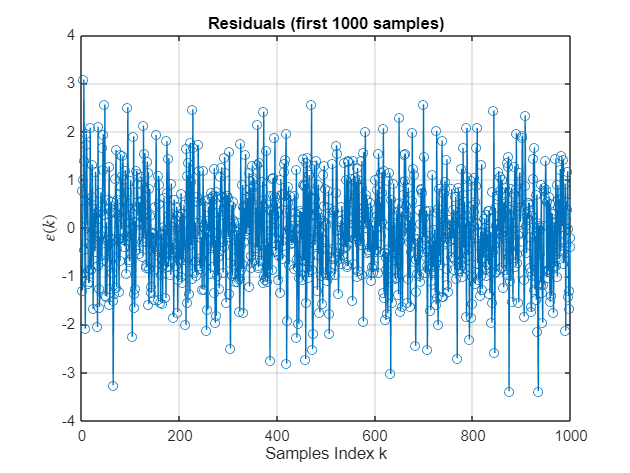

finalTheta = ThetaRLS;
n_final = n_min;

epsilon = residuals(y_valid, finalTheta, n_final);   % residuals: length = N - n_final

figure();
plot(t(1:1000), epsilon(1:1000), 'o-');              %plotting the graph of the residuals
grid on;
xlabel("Samples Index k");
ylabel('$\varepsilon(k)$','Interpreter','latex');
title(sprintf("Residuals (first 1000 samples)"));

drawnow;

And then we can perform the Whiteness Test in order to validate the model:

Accept H0: the model is accepted and the signal is white


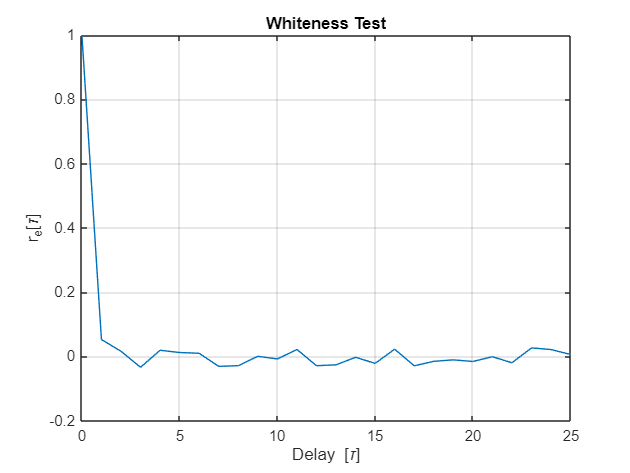

whiteTest(y_valid,epsilon,n_final);

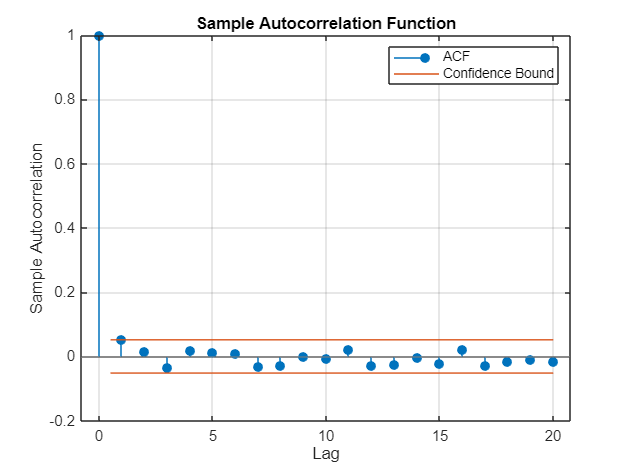

figure();                                     
autocorr(epsilon);

As we can see from the test and from the autocorrelation the model is valid with complexity **p** = 6 and $\theta$ computed with the RLS III algorithm.

# Exercise 2 - Classification

**1) - Understanding the feature set in space:**

[FeatureSet] = ClassifyThose(N,Student,Matriculation);
Utrain  = FeatureSet.Utrain;
Ytrain  = FeatureSet.Ytrain;
Utest   = FeatureSet.Utest;
Ytest   = FeatureSet.Ytest;

We need to split the training set into different classes, and then plot the data.

Looking at the given samples, we can clearly see that the input space is divided into 5 different classess and it's a two-dimensional space.

We can now plot the *training data* to clearly see the 5 different classes with teir data and corresponding values.

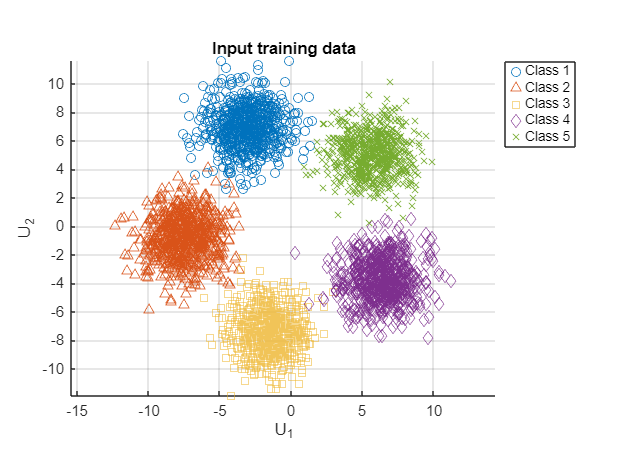

figure; hold on; grid on; axis equal;
plot(Utrain(Ytrain==1,1), Utrain(Ytrain==1,2), 'o');
plot(Utrain(Ytrain==2,1), Utrain(Ytrain==2,2), '^');
plot(Utrain(Ytrain==3,1), Utrain(Ytrain==3,2), 's');
plot(Utrain(Ytrain==4,1), Utrain(Ytrain==4,2), 'd');
plot(Utrain(Ytrain==5,1), Utrain(Ytrain==5,2), 'x');
xlabel('U_1'); ylabel('U_2');
legend('Class 1','Class 2','Class 3','Class 4','Class 5','Location','bestoutside');
title('Input training data'); hold off;

We can also plot the *test data* as well, as follows:

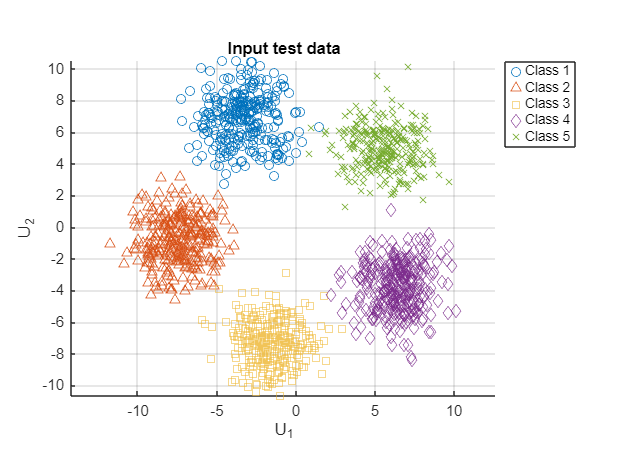

figure; hold on; grid on; axis equal;
plot(Utest(Ytest==1,1), Utest(Ytest==1,2), 'o');
plot(Utest(Ytest==2,1), Utest(Ytest==2,2), '^');
plot(Utest(Ytest==3,1), Utest(Ytest==3,2), 's');
plot(Utest(Ytest==4,1), Utest(Ytest==4,2), 'd');
plot(Utest(Ytest==5,1), Utest(Ytest==5,2), 'x');
xlabel('U_1'); ylabel('U_2');
legend('Class 1','Class 2','Class 3','Class 4','Class 5','Location','bestoutside');
title('Input test data'); hold off;

The dataset is therefore divided in five different classes, so we have to deal with a multiclass classification problem.

**2 & 3) - Defining the required classification algorithm and verify and test the classification:**

We have to deal with a probabilistic classification model. As requested by the exercise, we will classify using the **L*****inear Discriminant Analysis (LDA)***. 

- **Linear Discriminant Analysis**

We start assuming that the features $x \in \mathbb{R}^d\)$ come from $K$ classes with Gaussian densities and same *Covariance Matrix *$\Sigma$, so:

                                                                                                    
$$x \mid \mathcal{C}_k \sim \mathcal{N}(\mu_k,\;\Sigma), \qquad k=1,\dots,K$$


and the probability density function for each *class* is:

                                                                                                    
$$f_{u}(u(t)\mid \mathcal{C}_i)
=\frac{1}{(2\pi)^{r/2}\sqrt{\det(\Sigma)}}\,
\exp\!\Big(-\frac12\,(u(t)-\mu_i)^\top \Sigma^{-1}(u(t)-\mu_i)\Big),
\qquad i=1,\dots,M .$$


Then, it follows that the Bayes' theorem can be written as:

                                                                                                    
$$P(\mathcal{C}_i \mid u(t))
= \frac{f_u(u(t)\mid \mathcal{C}_i)\,P(\mathcal{C}_i)}{\sum_{k=1}^M f_u(u(t)\mid \mathcal{C}_k)\,P(\mathcal{C}_k)}
= \frac{e^{z_i(t)}}{\sum_{k=1}^M e^{z_k(t)}} \space\space\space\space\space (Softmax \space Function)$$


Considering the above hypotesis, the linear discriminant for the class $K$ is:

                                                                                                    
$$z_i(t) \;=\; u(t)^\top \Sigma^{-1} \mu_i \;-\; \frac12\,\mu_i^\top \Sigma^{-1}\mu_i \;+\; \log P(\mathcal{C}_i) = u^T(t)\beta + \beta_0 = \varphi^T(t)\theta_i$$


Then, the input space $U = R^r$ can thus be divided into $M$ regions defined by a set of $M$ hyperplanes. Each hyperplane represents the *linear decision boundary* between two classes. More precisely, the hyperplane separating classes $k$ and $j$ is described by the equation:

                                                                                                    
$$z_k(t)-z_j(t)=0  \space that \space is \space \varphi^T(t)(\theta_k - \theta_j) = 0$$


where $\mu_k$ is the mean of a class, $P(\mathcal{C}_i)$ is the prior probability and $\Sigma$ is the estimated covariance on the train data, which can be written as:

                                                                                                    
$$\widehat{\mu}_i \;=\; \frac{1}{N_i}\!\!\sum_{\space t:\,y(t)=i}\! u(t)  \space\space\space i =1,2,...,M
$$


                                                                                                    
$$\widehat{\Sigma} \;=\; \sum_{i=1}^{M}\frac{1}{N } \;\sum_{t :y(t) = y^i} \bigl(u(t) - \hat{\mu_i}\bigr)\bigl(u(t) - \hat{\mu_i}\bigr)^\top
$$


                                                                                                    
$$\widehat{P}(\mathcal{C}_i)=\frac{N_i}{N}  \space\space\space i =1,2,...,M$$


where $N_i$is the number of inputs belonging to class $C_i$.

Then, a new input $u(t)
$ is assigned to the class $C_k$ such that:

                                                                                                    
$$k \;=\; \arg\max_{i \in\{1,2,...,M\}} \widehat{P}(C_i\space|\spaceu(t))
$$


We can choose the *LDA* because it gives simple linear decision boundaries, is optimal in *Bayesan sense* and it has low computational complexity. So if we have to deal with linear boundaries it's a perfect algorithm to the probabilistic model classification.

To  use the **LDA** we can implement the following **functions**:

- `lda_train:` function which computes estimations of class means $\hat{\mu}_i$, common covariances $\hat{\Sigma}$, and prior probabilities $\hat P(\mathcal{C}_i)$ from the train dataset.

- `softmaxFunct:` function which computes the Softmax Function to compute the posterior probabilities and the argmax decision

- `plotClassifier:` function which plots the feature sets including the linear boundaries and shows the mismatches of the input points in the dataset.

We now compute $\theta$ to use for $z_i(t)$, which will be used in the Softmax Function:

% Train LDA
model = lda_train(Utrain, Ytrain);                                          %mu_i, sigma and prior are computed

% Computation of theta = [beta | beta0] for each row

finalTheta = [ (model.Sinv * model.mu.').' , ...                                       % beta = Sigma^{-1} mu
    -0.5*sum((model.mu*model.Sinv).*model.mu,2) + log(model.prior+eps)                 % beta0
];

disp('Theta  (rows = classes, cols = [beta1 .. betaD   beta0]):');

Theta  (rows = classes, cols = [beta1 .. betaD   beta0]):


disp(finalTheta);

   -1.4267    3.2799  -15.2416
   -3.3353   -0.2858  -14.1475
   -0.6056   -3.4132  -14.6529
    2.9231   -1.7949  -14.3903
    2.4979    2.3068  -14.5360



And we now compute the *posterior probabilities* with the *Softmax Function*, as follows:

%Softmax computation

% Prediction for each i
Yf = zeros(size(Utrain,1),1);                                               %vector to collect values of the estimate of the output

for i = 1:size(Utrain,1)
    [y_i, post_i] = softmaxFunct(Utrain(i,:), finalTheta, model.classes);   %computation of Softmax function through the function implemented
    Yf(i) = y_i;                                                            
end

And then we plot the feature set with the linear boundaries and the mismatches inputs $u(t)$ in the training set: 

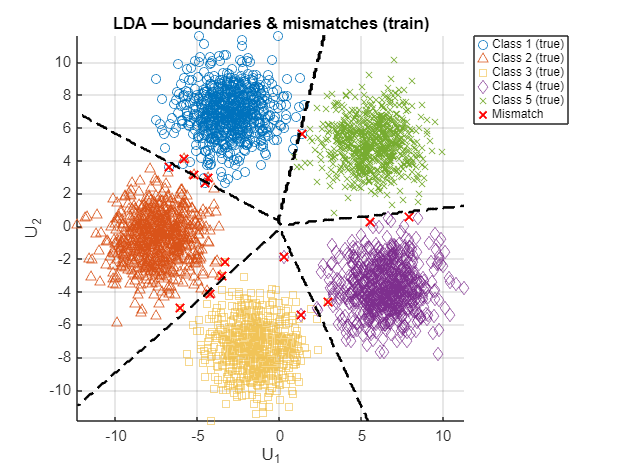

plotClassifier(Utrain, Ytrain, Yf, finalTheta, ...                          %using the plotClassifier function
               'LDA — boundaries & mismatches (train)', model.classes);

drawnow;

We can see that we don't have a lot of misclassfied point (the red x). With 5 classes, under the assumption that they are well separated Gaussian classes and with same covariance matrix, it’s not rare to see **few training errors**. So we can say that almost all the samples are correctly classified.

Now we can also compute the *error rate* among all the classes, in this way we can test the classification reliability. To do so, we'll use another **function**:

- `errRate`: function which computes the error rate for each class and the total error rate among all classes.

% Computing error rate for each class
classCount = unique(Ytrain);

[errRates, errTest] = errRate(Ytrain, Yf, classCount);

for i = 1:numel(classCount)
    fprintf('Class %d - Error rate: %.2f%%\n', classCount(i), 100*errRates(i));
end

Class 1 - Error rate: 0.43%
Class 2 - Error rate: 0.57%
Class 3 - Error rate: 0.58%
Class 4 - Error rate: 0.29%
Class 5 - Error rate: 0.28%


While the error rate for the whole training set:

% Computing error rate on Training set
fprintf('Overall training error rate: %.2f%%\n', 100*errTest);

Overall training error rate: 0.43%


As we can see (and as we could expect from the graph) the error rate remain very low.

Last of all, we'll use our classificator on the **test set** and we verify the result:

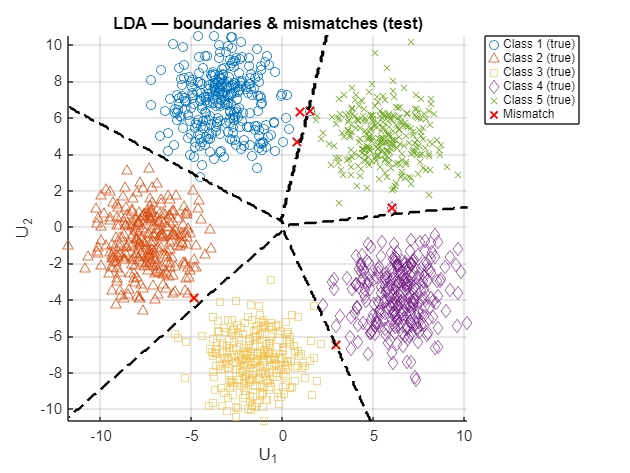

Yf = zeros(size(Utest,1),1);                                               %vector to collect values of the estimate of the output

for i = 1:size(Utest,1)
    [y_i, post_i] = softmaxFunct(Utest(i,:), finalTheta, model.classes);   %computation of Softmax function through the function implemented
    Yf(i) = y_i;                                                            
end
plotClassifier(Utest, Ytest, Yf, finalTheta, ...                           %using the plotClassifier function
               'LDA — boundaries & mismatches (test)', model.classes);

Also in this case, the *number of misclassified points is low*. We can notice that the mismatches are less than in the case of the training set, but this is natural, because in the test set we have less samples. Moreover, we can do the error rate in test set too:

%Computing error rate for each class
classCount = unique(Ytest);

[errRates, errTest] = errRate(Ytest, Yf, classCount);

for i = 1:numel(classCount)
    fprintf('Class %d - Error rate: %.2f%%\n', classCount(i), 100*errRates(i));
end

Class 1 - Error rate: 0.34%
Class 2 - Error rate: 0.00%
Class 3 - Error rate: 0.65%
Class 4 - Error rate: 0.32%
Class 5 - Error rate: 0.69%


% Computing error rate on whole Test set
fprintf('Overall training error rate: %.2f%%\n', 100*errTest);

Overall training error rate: 0.40%


We can conclude that also for the test set the classification is correct almost for every sample and the error rate remain very low (and almost smilar to the one of the training set). Globally, we have tested and verified the correctness of the classification technique. This confirm the fact that the LDA is a very good linear classificator for the classification of probabilistic models.